# 交互教学 01：配电网时序潮流与节点电压

本节研究辐射状配电网在 24 小时内的电压变化。三个光伏节点各接入 0.8 MW 光伏，不配置储能。

## 使用方法

先将 MATLAB 当前文件夹切换到 interactive。首次点击“全部运行”。修改计算参数后重新运行；查看时段、支路或节点的滑块只更新所在节的图形。

lesson = ess_live_setup();
export_figures = true;

## 个人学号与本次计算条件

修改学号后重新运行后续各节。算例、负荷系数和候选节点沿用课程统一规则。

Stu_ID = 242400011;
XY=mod(Stu_ID,100);
X_digit=floor(XY/10); Y_digit=mod(XY,10);
alpha=1+0.002*XY;
if ismember(Y_digit,[0 1 2 3])
    case_name='case_nongcun';
elseif ismember(Y_digit,[4 5 6])
    case_name='case_chengshi_A';
else
    case_name='case_kaifaqu_A';
end
if ismember(X_digit,[0 1 2])
    study_buses=[4 9 14]; model_type='A';
elseif ismember(X_digit,[3 4 5])
    study_buses=[5 11 16]; model_type='B';
else
    study_buses=[6 13 17]; model_type='C';
end
profiles=load(fullfile(lesson.cases,'profiles_24h.mat'));
T=profiles.T; dt=1;
load_curve_pu=profiles.load_curve_pu; pv_curve_pu=profiles.pv_curve_pu;
price_MWh=profiles.price_MWh; price_kWh=profiles.price_kWh;
disp(table(Stu_ID,string(case_name),alpha,string(model_type),string(mat2str(study_buses)),...
    'VariableNames',{'StudentID','Case','LoadMultiplier','Objective','StudyNodes'}));

    StudentID         Case         LoadMultiplier    Objective    StudyNodes
    _________    ______________    ______________    _________    __________

    2.424e+08    "case_nongcun"        1.022            "A"       "[4 9 14]"



mpc_base=loadcase(case_name);
pv_buses=study_buses;

## 负荷与光伏参数

功率使用 MW、Mvar，支路阻抗使用标幺值，节点电压使用标幺值。算例已完成阻抗换算。修改演示负荷系数后重新运行。

load_multiplier = 1;
alpha=(1+0.002*XY)*load_multiplier;
P_pv_peak_MW=0.8;

## 查看节点数据

节点有功与无功负荷分别位于第 3、4 列。先查看前十个节点，再确认光伏接入位置。

disp(array2table(mpc_base.bus(1:min(10,end),[1 3 4 10]),'VariableNames',{'Node','Load_MW','Load_Mvar','Base_kV'}));

    Node    Load_MW    Load_Mvar    Base_kV
    ____    _______    _________    _______

      1          0           0       12.66 
      2      0.122        0.03       12.66 
      3          0           0       12.66 
      4      0.075       0.019       12.66 
      5          0           0       12.66 
      6      0.065       0.016       12.66 
      7      0.025       0.006       12.66 
      8      0.017       0.004       12.66 
      9      0.042       0.011       12.66 
     10      0.038        0.01       12.66 



## 构造逐时负荷并计算交流潮流

各时段均从基准算例重新构造负荷，光伏有功从节点负荷中扣除。


$$P_{i,t}^{\mathrm{net}}=\alpha P_{i,0}^{\mathrm{load}}p_t^{\mathrm{load}}-P_{i,t}^{\mathrm{pv}}$$


N_bus      = size(mpc_base.bus, 1);
V_bus_24h  = zeros(N_bus, T);
P_loss_24h = zeros(T, 1);
mpopt      = mpoption('verbose', 0, 'out.all', 0);
for t = 1:T
    mpc_t = mpc_base;
    mpc_t.bus(:, 3) = mpc_base.bus(:, 3) * alpha * load_curve_pu(t);
    mpc_t.bus(:, 4) = mpc_base.bus(:, 4) * alpha * load_curve_pu(t);
    mpc_t.bus(pv_buses, 3) = mpc_t.bus(pv_buses, 3) - P_pv_peak_MW * pv_curve_pu(t);
    results = runpf(mpc_t, mpopt);
    assert(results.success==1,'第 %d 时段交流潮流未收敛。',t);
    V_bus_24h(:, t) = results.bus(:, 8);
    P_loss_24h(t)   = sum(real(get_losses(results)));
end

## 最低电压与全天电能损耗

输出最低电压及其节点、时段，并将逐时有功损耗对时间求和。


$$E_{\mathrm{loss}}=\sum_{t=1}^{T}P_{\mathrm{loss},t}\Delta t$$


[min_V,ix]=min(V_bus_24h(:));
[min_bus,min_hour]=ind2sub(size(V_bus_24h),ix);
DailyLoss_MWh=sum(P_loss_24h)*dt;
disp(table(min_V,min_bus,min_hour,DailyLoss_MWh));

     min_V     min_bus    min_hour    DailyLoss_MWh
    _______    _______    ________    _____________

    0.95105      14          19          1.1477    



## 交互查看节点电压

移动时段滑块，观察馈线上各节点电压；移动节点滑块，查看所选节点的全天电压。节点编号按当前算例范围取值。

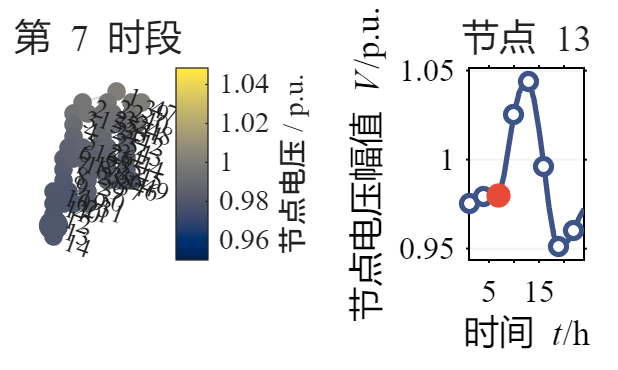

view_hour = 7;
view_node = 13;
view_node=min(view_node,N_bus);
fig_voltage=ess_live_view('voltage',mpc_base,V_bus_24h,view_hour,view_node);

## 保存本次课堂结果

导出到 interactive/results，不覆盖原始脚本的图形文件。

out_dir=fullfile(lesson.results,sprintf('Lesson01_%d',Stu_ID));
if export_figures, ess_live_export(fig_voltage,out_dir,'Voltage_Explorer'); end

Lesson_Stats=struct('Lesson',1,'MinVoltage',min_V,'DailyLoss_MWh',DailyLoss_MWh);

## 练习

将附加负荷倍率由 1.00 调整为 1.10。计算前先判断最低电压和电能损耗如何变化；计算后记录节点、时段和数值，并解释变化原因。

## 图片添加和导出

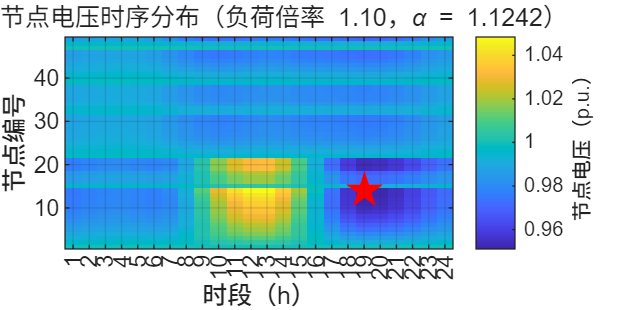

%% 导出 Interactive01 的全部报告图和数据
report_dir = 'D:\校内课程作业\累累的实习\第一周报告\interaction01图';

if ~exist(report_dir,'dir')
    mkdir(report_dir);
end

% 用负荷倍率区分两次运行的文件
tag = ['load_' strrep(sprintf('%.2f',load_multiplier),'.','p')];
bus_ids = mpc_base.bus(:,1);

% 自动选取午间光伏峰值时段和晚高峰时段
[~,noon_hour] = max(pv_curve_pu);

evening_candidates = find( ...
    (1:T)' > noon_hour & ...
    pv_curve_pu(:) <= 0.05*max(pv_curve_pu));

if isempty(evening_candidates)
    evening_candidates = (1:T)';
end

[~,k] = max(load_curve_pu(evening_candidates));
evening_hour = evening_candidates(k);

%% 图1：全网所有节点、所有时段电压时序分布
fig1 = figure('Color','w','Position',[100 100 1200 600]);

imagesc(1:T,bus_ids,V_bus_24h);
set(gca,'YDir','normal');
colormap(gcf,parula);

cb = colorbar;
cb.Label.String = '节点电压（p.u.）';

hold on;
plot(min_hour,bus_ids(min_bus),'rp', ...
    'MarkerSize',13,'MarkerFaceColor','r');

xlabel('时段（h）');
ylabel('节点编号');
title(sprintf('全网节点电压时序分布（负荷倍率 %.2f，\\alpha = %.4f）', ...
    load_multiplier,alpha));
xticks(1:T);
grid on;

exportgraphics(fig1, ...
    fullfile(report_dir,[tag '_01_全网电压时序分布.png']), ...
    'Resolution',300);

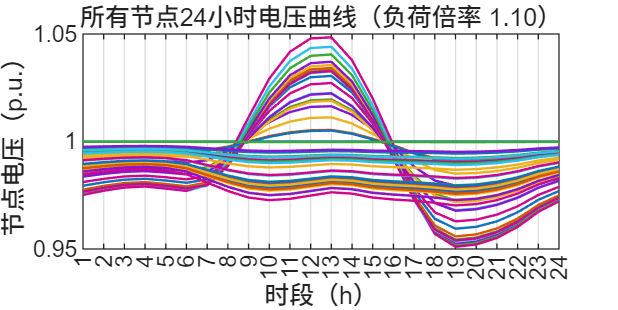


%% 图2：所有节点的24小时电压曲线
fig2 = figure('Color','w','Position',[100 100 1200 600]);

plot(1:T,V_bus_24h','LineWidth',0.9);
xlabel('时段（h）');
ylabel('节点电压（p.u.）');
title(sprintf('所有节点24小时电压曲线（负荷倍率 %.2f）',load_multiplier));
xlim([1 T]);
xticks(1:T);
grid on;

exportgraphics(fig2, ...
    fullfile(report_dir,[tag '_02_所有节点电压曲线.png']), ...
    'Resolution',300);

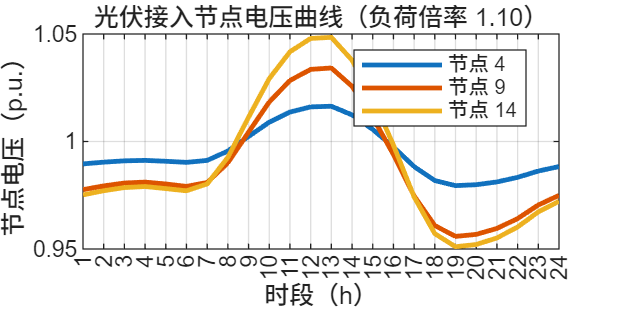


%% 图3：光伏接入节点4、9、14的24小时电压曲线
fig3 = figure('Color','w','Position',[100 100 1200 600]);

plot(1:T,V_bus_24h(study_buses,:)','LineWidth',1.8);
xlabel('时段（h）');
ylabel('节点电压（p.u.）');
title(sprintf('光伏接入节点电压曲线（负荷倍率 %.2f）',load_multiplier));
xlim([1 T]);
xticks(1:T);
grid on;

legend(arrayfun(@(b)sprintf('节点 %d',b),study_buses, ...
    'UniformOutput',false),'Location','best');

exportgraphics(fig3, ...
    fullfile(report_dir,[tag '_03_光伏节点电压曲线.png']), ...
    'Resolution',300);

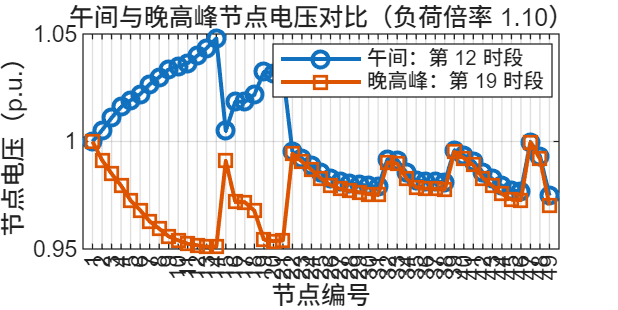


%% 图4：午间与晚高峰的全网节点电压分布
fig4 = figure('Color','w','Position',[100 100 1100 550]);

plot(bus_ids,V_bus_24h(:,noon_hour),'-o', ...
    'LineWidth',1.5,'DisplayName',sprintf('午间：第 %d 时段',noon_hour));
hold on;

plot(bus_ids,V_bus_24h(:,evening_hour),'-s', ...
    'LineWidth',1.5,'DisplayName',sprintf('晚高峰：第 %d 时段',evening_hour));

xlabel('节点编号');
ylabel('节点电压（p.u.）');
title(sprintf('午间与晚高峰节点电压对比（负荷倍率 %.2f）',load_multiplier));
xticks(bus_ids);
grid on;
legend('Location','best');

exportgraphics(fig4, ...
    fullfile(report_dir,[tag '_04_午间与晚高峰电压对比.png']), ...
    'Resolution',300);

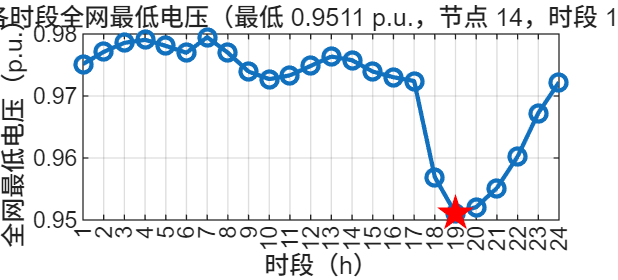


%% 图5：各时段全网最低电压
[minV_each_hour,~] = min(V_bus_24h,[],1);

fig5 = figure('Color','w','Position',[100 100 1100 500]);

plot(1:T,minV_each_hour,'-o','LineWidth',1.6);
hold on;
plot(min_hour,min_V,'rp','MarkerSize',13,'MarkerFaceColor','r');

xlabel('时段（h）');
ylabel('全网最低电压（p.u.）');
title(sprintf('各时段全网最低电压（最低 %.4f p.u.，节点 %d，时段 %d）', ...
    min_V,min_bus,min_hour));
xlim([1 T]);
xticks(1:T);
grid on;

exportgraphics(fig5, ...
    fullfile(report_dir,[tag '_05_各时段最低电压.png']), ...
    'Resolution',300);

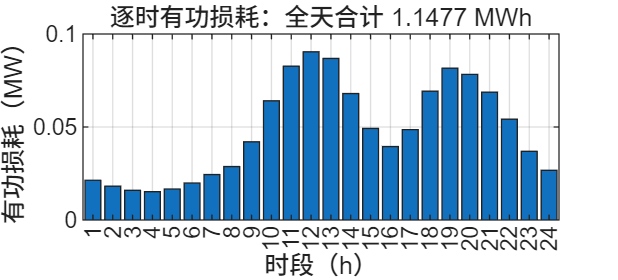


%% 图6：逐时有功损耗与全天电能损耗
fig6 = figure('Color','w','Position',[100 100 1100 500]);

bar(1:T,P_loss_24h);
xlabel('时段（h）');
ylabel('有功损耗（MW）');
title(sprintf('逐时有功损耗：全天合计 %.4f MWh',DailyLoss_MWh));
xlim([0.5 T+0.5]);
xticks(1:T);
grid on;

exportgraphics(fig6, ...
    fullfile(report_dir,[tag '_06_逐时网损.png']), ...
    'Resolution',300);


%% 图7：程序原有的交互电压查看图
if exist('fig_voltage','var') && isvalid(fig_voltage)
    exportgraphics(fig_voltage, ...
        fullfile(report_dir,[tag '_07_电压交互查看图.png']), ...
        'Resolution',300);
end


%% 保存关键结果，防止第二次运行后覆盖第一轮数据
key_results = table( ...
    Stu_ID,string(case_name),load_multiplier,alpha, ...
    min_V,min_bus,min_hour,DailyLoss_MWh,noon_hour,evening_hour, ...
    'VariableNames',{ ...
    'StudentID','Case','LoadMultiplier','Alpha', ...
    'MinVoltage_pu','MinBus','MinHour','DailyLoss_MWh', ...
    'NoonHour','EveningHour'});

writetable(key_results, ...
    fullfile(report_dir,[tag '_关键结果.csv']));

save(fullfile(report_dir,[tag '_计算数据.mat']), ...
    'V_bus_24h','P_loss_24h','key_results', ...
    'min_V','min_bus','min_hour','DailyLoss_MWh', ...
    'noon_hour','evening_hour');

disp(key_results);

    StudentID         Case         LoadMultiplier    Alpha     MinVoltage_pu    MinBus    MinHour    DailyLoss_MWh    NoonHour    EveningHour
    _________    ______________    ______________    ______    _____________    ______    _______    _____________    ________    ___________

    2.424e+08    "case_nongcun"         1.1          1.1242       0.95105         14        19          1.1477           12           19     



fprintf('全部图片和数据已导出到：\n%s\n',report_dir);

全部图片和数据已导出到：
D:\校内课程作业\累累的实习\第一周报告\interaction01图
